% image
imageFolder = 'imagethree/cu_0.025/';
imageFiles = dir(fullfile(imageFolder, '*.png')); % フォーマットに応じて変更
imgcnt = 3;
imagePath = fullfile(imageFolder, imageFiles(imgcnt).name);
%color space
cform1 = makecform('xyz2xyl')

cform1 = フィールドをもつ struct :
            c_func: @xyz2xyl
     ColorSpace_in: 'xyz'
    ColorSpace_out: 'xyl'
          encoding: 'double'
             cdata: [1×1 struct]


cform2 = makecform('xyl2xyz')

cform2 = フィールドをもつ struct :
            c_func: @xyl2xyz
     ColorSpace_in: 'xyl'
    ColorSpace_out: 'xyz'
          encoding: 'double'
             cdata: [1×1 struct]


%callibration
callibration_Path = 'callibration/'

callibration_Path = 'callibration/'

spectrum_data = readmatrix(fullfile(callibration_Path,'spectr.csv'));
c = tnt.RgbConverter(spectrum_data);
gamma_converter =load(fullfile(callibration_Path,"gamma_converter.mat")).gamma_converter;

%---input sRGB already tonemapped---

originalImg = double(imread(imagePath));
srgbImgin = cat(3,originalImg(:,:,1)/255,originalImg(:,:,2)/255,originalImg(:,:,3)/255);
xyzImgin = rgb2xyz(srgbImgin);
xyYImgin = applycform(xyzImgin,cform1);
Ychan = xyYImgin(:,:,3)

Ychan =     0.5972    0.5972    0.5906    0.5906    0.5906    0.5841    0.5841    0.5776    0.5776    0.5776    0.5711    0.5711    0.5711    0.5647    0.5647    0.5647    0.5583    0.5583    0.5583    0.5520    0.5520    0.5520    0.5457    0.5457    0.5457    0.5395    0.5395    0.5333    0.5333    0.5333    0.5333    0.5271    0.5271    0.5210    0.5210    0.5210    0.5149    0.5149    0.5149    0.5089    0.5089    0.5089    0.5029    0.5029    0.5029    0.5029    0.4969    0.4969    0.4969    0.4910
    0.5906    0.5906    0.5841    0.5841    0.5841    0.5776    0.5776    0.5776    0.5711    0.5711    0.5711    0.5647    0.5647    0.5647    0.5583    0.5583    0.5520    0.5520    0.5520    0.5457    0.5457    0.5457    0.5395    0.5395    0.5395    0.5333    0.5333    0.5333    0.5271    0.5271    0.5271    0.5210    0.5210    0.5210    0.5149    0.5149    0.5149    0.5089    0.5089    0.5089    0.5076    0.5029    0.5029    0.5029    0.4969    0.4969    0.4969    0.4969    0.4910 

LDR_Y = Ychan*206%0.3605/0.0055;

LDR_Y =   123.0236  123.0236  121.6675  121.6675  121.6675  120.3202  120.3202  118.9816  118.9816  118.9816  117.6517  117.6517  117.6517  116.3306  116.3306  116.3306  115.0181  115.0181  115.0181  113.7143  113.7143  113.7143  112.4192  112.4192  112.4192  111.1328  111.1328  109.8549  109.8549  109.8549  109.8549  108.5857  108.5857  107.3251  107.3251  107.3251  106.0730  106.0730  106.0730  104.8296  104.8296  104.8296  103.5946  103.5946  103.5946  103.5946  102.3682  102.3682  102.3682  101.1503
  121.6675  121.6675  120.3202  120.3202  120.3202  118.9816  118.9816  118.9816  117.6517  117.6517  117.6517  116.3306  116.3306  116.3306  115.0181  115.0181  113.7143  113.7143  113.7143  112.4192  112.4192  112.4192  111.1328  111.1328  111.1328  109.8549  109.8549  109.8549  108.5857  108.5857  108.5857  107.3251  107.3251  107.3251  106.0730  106.0730  106.0730  104.8296  104.8296  104.8296  104.5669  103.5946  103.5946  103.5946  102.3682  102.3682  102.3682  102.3682  101.1503 

lum_av = mean(Ychan(:));
disp(lum_av);

    0.3605




xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform2);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);


xyzImgcom = rgb2xyz(digital_rgb);
xyYImgcom = applycform(xyzImgcom,cform1);
Ychan_com = xyYImgcom(:,:,3);
lum_av = mean(Ychan_com(:));
disp(lum_av);

    0.6720



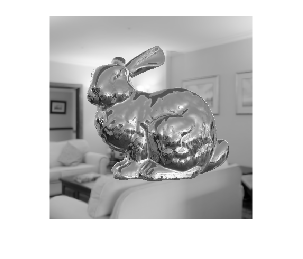

%}
%---input sRGB already tonemapped---
%---input sRGB don't tonemapped---
%{
originalImg = double(imread(imagePath));
srgbImgin = cat(3,originalImg(:,:,1)/255,originalImg(:,:,2)/255,originalImg(:,:,3)/255);
xyzImgin = rgb2xyz(srgbImgin);
xyYImgin = applycform(xyzImgin,cform1);
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
%LDR_Y = xyYImgin(:,:,3)*100;
%LDR_Y = ReinhardTMO(xyYImgin(:,:,3))*100;
%LDR_Y = ReinhardTMO(xyYImgin(:,:,3),1,1,'global',8,1.19)*100;
LDR_Y = Reinhard(xyYImgin(:,:,3),1)*100;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform2);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---input sRGB don't tonemapped---
% confirm
%{
max(max(max(linear_rgb)))
min(min(min(linear_rgb)))

max(max(max(digital_rgb)))
min(min(min(digital_rgb)))
%}
imshow(srgbImgin);

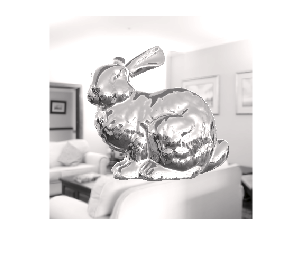

imshow(digital_rgb);